clc;
close all;
clear;
addpath('videos'); 

#### Note: it might be necessary to open matlab with:

## Change detection algorithm

- TAU1 tells us how much a pixel has to change with respect to the static beckground to be considered part of the foreground (values between 10/15 with low noise - to 30/40 for noisy videos). If it is too low we highlight noise, too high you miss some important information

- TAU2 used to define if a pixel is moving or not and consequently whether or not to update the background. If the pixel is moving you keep the old background. (values usually between 2/5 for slow movement - 10/20 for noisy scenes). Tau2 describe sensibility to movement, if it is too high you update also moving pixels, if it is too low you do not update the background and it remains fixed.

- APHA is the velocity of adaptation to changes, its value has to be between (0,1). If alpha=1 the background changes completely and becomes the new frame, instead with alpha=0 we keep the old background still. The alpha value is set to 0.02 where we take a small percentage of the current frame in comparison to the static background.

- The first binary map relates to using the static background to detect changes.

- The second binary map relates to using the running average to detect changes. It is noticeable that the running average method is less sensitive to noise and cotinuous light changes.

If we use: 

- (10, 0.7, 5) what we obtain for the static background is a binary map with a lot of white pixels, so probably we have to set a higher threshold in order to avoid nose's influence. For the moving average instead we adjust the background too fast (too big alpha) and the binary map contains only noise.

- (20, 0.02, 5) we obtain better results. For the static part we capture less noisy pixels and only changes due to light shadows. For the running average, the background is adjusted slowly but consistently and in the binary map we see only smaller changes, for instance the movement of the shadows in last frames. What happened in the first instants is no longer visible in the end, as the change in background considered.

Background computed from 58 frames (60.00 seconds)


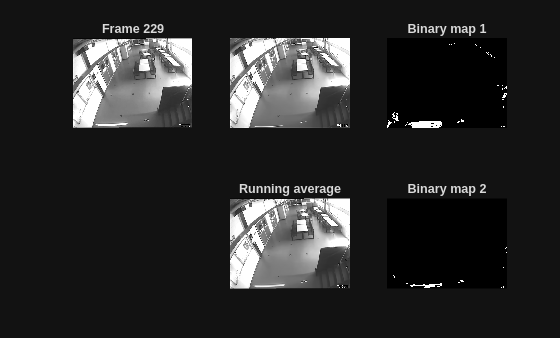

video1 = "luce_vp_1part.mp4";

compareCDAlgo(video1, 20, 0.02, 5)

## Change detection optical flow

Needed input values:

- TAU1 in this case the video shows a much more complex motion, so a bigger value is needed to capture only effective changes, otherwise the binary map would be completely white. We used 35.

- ALPHA we started with a small value (0,02) but then we realized that the background was updating too slowly with respect to the frames and so moved to a higher value (0.2) to have a faster behaviour. 

- TAU2 we used higher values with respect to the previous case because we need less sensitivety to changes, we want to avoid a full white binary map. Before we tried with 10 and then increased to 20.

- W is the size of the window used to define the neighbourhood of the Lucas Kanade algorithm. If we increase the size too much then we loose the sharp boundaries of the moving object. A small window picks up on fine details but is very sensitive to noise. After trail and error we found that a window size of 8 was optimal.  

- The opitical flow map represents the apparent motion of objects. Here the previous frame is compared to the current frame. The motion seen is either caused by the camera thats why we detect the table and the wall as the camera is zoom out or from the object such as the movement of the person and the ball.

video2 = "tennis_2part.mp4";
compareCDOF(video2,35,0.2,20,8) 

## Tracker

Needed input values:

- TAU1 in this case the video does not have a complex motion, so a medium value is needed to capture the motion of the people. We used a value of 15

- ALPHA we started with a small value (0,002) but then we realized that the background was updating too slowly with respect to the frames. This left a shady of the person in the background and so moved to a higher value (0.5) to have a faster behaviour. We tried 0.3 but that was not updating the model fast enough. This means that it never cleared the previous position (starting position of the person) and kepts the ghost version which causes the model  to loose track of the person when they walked back. Or it captured the light change as the "blob"

- TAU2 we used lower value with respect to the previous case because the person stands still every now and then so it is important to take in the slightess movements to continous track him. This does lead to also capturing noise as we notice from the roughness of the line, however, it continuously monitors the desired person. With a high alpha and a high tau2 it creates a balance where the alpha does not erase the person if they stand for too long in the same spot.

RUN THIS PART FROM THE Runfile.m 

% video3 = "DibrisHall_3part.mp4";
% segmantAndTrack(video3,15,0.5,10)